a_model_setup

## single case

model.u_fun = @(t) 9 * sin(model.omega * t);
[t, x] = ode15s(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);
tip_disp = x(:,1:2) * model.Phiell;  % [N x 1]
[t_lin, x_lin] = f_get_last_n_periods(t, tip_disp, 10);
[A_vec,B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
Amplitude = sqrt(sum(A_vec.^2 + B_vec.^2, "all"))

Amplitude = 0.0186

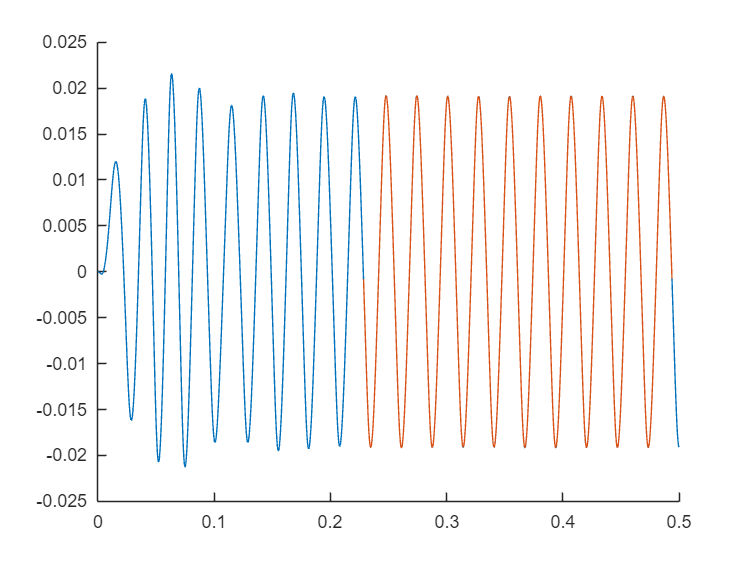

figure;
hold on;
plot(t, tip_disp)
plot(t_lin, x_lin)

## Sweep

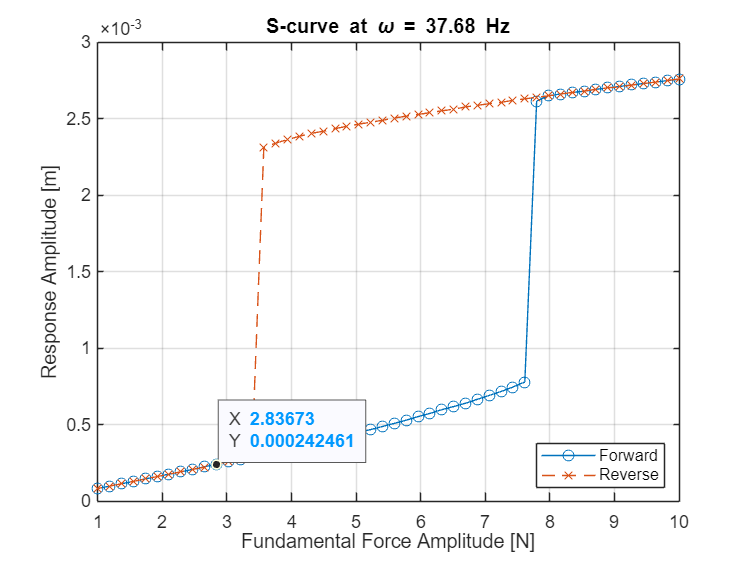

u_vals = linspace(1, 10, 50);  % Forward sweep
u_vals_rev = fliplr(u_vals);  % Reverse sweep

A_response_fwd = zeros(size(u_vals));
A_force_fwd = zeros(size(u_vals));

A_response_rev = zeros(size(u_vals));
A_force_rev = zeros(size(u_vals));

% ---------- Forward sweep ----------
for i = 1:length(u_vals)
    u1 = u_vals(i);
    model.u_fun = @(t) u1 * sin(model.omega * t);

    [t, x] = ode15s(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);
    % tip_disp = x(:,1:2) * model.Phiell;
    tip_disp = x(:, 1);
    [t_lin, x_lin] = f_get_last_n_periods(t, tip_disp, 10);
    [A_vec, B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
    A_response_fwd(i) = sqrt(sum(A_vec.^2 + B_vec.^2));

    f_t = model.G * x(:,5);
    [t_lin, x_lin] = f_get_last_n_periods(t, f_t, 10);
    [A_vec, B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
    A_force_fwd(i) = sqrt(sum(A_vec.^2 + B_vec.^2));

    x0 = x(end,:)';  % continue from last state
end

% ---------- Reverse sweep ----------
x0 = zeros(5,1);
for i = 1:length(u_vals_rev)
    u1 = u_vals_rev(i);
    model.u_fun = @(t) u1 * sin(model.omega * t);

    [t, x] = ode15s(@(t,x) f_beam_shaker_model(t, x, model), tspan, x0);
    % tip_disp = x(:,1:2) * model.Phiell;
    tip_disp = x(:, 1);
    [t_lin, x_lin] = f_get_last_n_periods(t, tip_disp, 10);
    [A_vec, B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
    A_response_rev(i) = sqrt(sum(A_vec.^2 + B_vec.^2));

    f_t = model.G * x(:,5);
    [t_lin, x_lin] = f_get_last_n_periods(t, f_t, 10);
    [A_vec, B_vec] = f_get_fft_components(t_lin, x_lin, model.omega, model.harmonics);
    A_force_rev(i) = sqrt(sum(A_vec.^2 + B_vec.^2));

    x0 = x(end,:)';  % continue from last state
end

figure;
% plot(A_force_fwd, A_response_fwd, 'o-', 'DisplayName', 'Forward');
plot(u_vals, A_response_fwd, 'o-', 'DisplayName', 'Forward');
hold on;
% plot(A_force_rev, A_response_rev, 'x--', 'DisplayName', 'Reverse');
plot(u_vals_rev, A_response_rev, 'x--', 'DisplayName', 'Reverse');
xlabel('Fundamental Force Amplitude [N]');
ylabel('Response Amplitude [m]');
title(['S-curve at \omega = ', num2str(model.omega/(2*pi), '%.2f'), ' Hz']);
legend('Location','southeast');
grid on;

## plot u_vals vs forcing

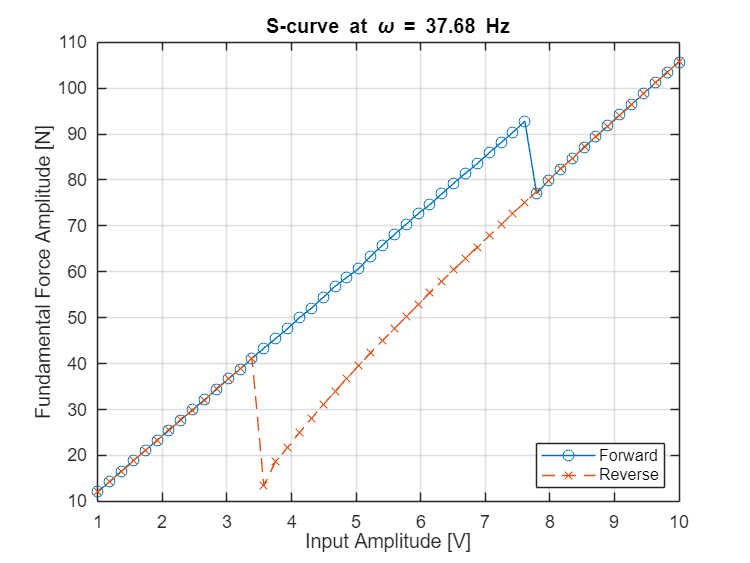

figure;
plot(u_vals, A_force_fwd, 'o-', 'DisplayName', 'Forward');
hold on;
plot(u_vals_rev, A_force_rev, 'x--', 'DisplayName', 'Reverse');
xlabel('Input Amplitude [V]');
ylabel('Fundamental Force Amplitude [N]');
title(['S-curve at \omega = ', num2str(model.omega/(2*pi), '%.2f'), ' Hz']);
legend('Location','southeast');
grid on;